# Feature 추출하기  

- extract_feature_v2 를 사용

- 여기서 충전시 온도가 이상값인 경우 적절한 값으로 대치한다.

- extract_feature_v3 를 사용 

- extract_feature_v2 을 기반으로 방전시 온도도 확인하고 이상값인 경우 이를 적절한 값으로 대치한다.

- extract_feature_v4 를 사용

- extract_feature_v3 을 기반으로 rest time 중에 regeneration 한 cycle을 제거한다. 

시계열 데이타이지만 각 피쳐와 Capacity는  시계열 모델이 아니라 일반적인 structural 모델이다.

실험결과 선택한 feature 에 따른 선형관계이므로 선택한 feature 의 outer는 제외시켜야 한다.

load B0005.mat
load B0006.mat
load B0007.mat
load B0018.mat
BAT1 =B0005;
BAT2 =B0006;
BAT3 =B0007; 
BAT4 =B0018; 


## 피쳐 얻어오기

array2table 로 테이블을 만들때 선형회구를 하기 위해 종속변수를 제일 뒤에 두어라

[cap,maxTemp,maxTimeDelta_org,maxTimeDelta,ohm,re_c,re_d,dmaxTemp,dmaxTimeDelta_org,dmaxTimeDelta] = extract_feature_v4(BAT1);
dataVector = [  maxTimeDelta' cap']; 
dataVectorAll = [maxTemp' maxTimeDelta'  ohm'  re_c' re_d', dmaxTemp' dmaxTimeDelta' cap'];


%{
[cap2,maxTemp2,maxTimeDelta2,abnormal2,ohm2,re_c2,re_d2] = extract_feature_v1(BAT2);
dataVectorAll2 = [maxTimeDelta2' maxTemp2' ohm2'  re_c2' re_d2' cap2'  ];
dataVector2 = [maxTimeDelta2' cap2'  ];

[cap3,maxTemp3,maxTimeDelta3,abnormal3,ohm3,re_c3,re_d3] = extract_feature_v1(BAT3);
dataVectorAll3 = [maxTimeDelta3' maxTemp3' ohm3'  re_c3' re_d3' cap3'  ];
dataVector3 = [maxTimeDelta3'  cap3'  ];
%}

%{
% extract_feature function has errors on BAT4
[cap4,maxTemp4,maxTimeDelta4,abnormal4,ohm4,re_c4,re_d4] = extract_feature_v1(BAT4);
dataVectorAll4 = [maxTimeDelta4' maxTemp4' ohm4'  re_c4' re_d4' cap4'  ];
dataVector4 = [maxTimeDelta4' cap4'  ];
%}

#### 상관관계 출력 

dischare temperature 가 max 가 되는까지의 시간은 cutoff voltage 까지 계속 증가하므로 유효한 변수가 아니다.

이것은 단지 사용자 패턴에 해당하는 것이다.

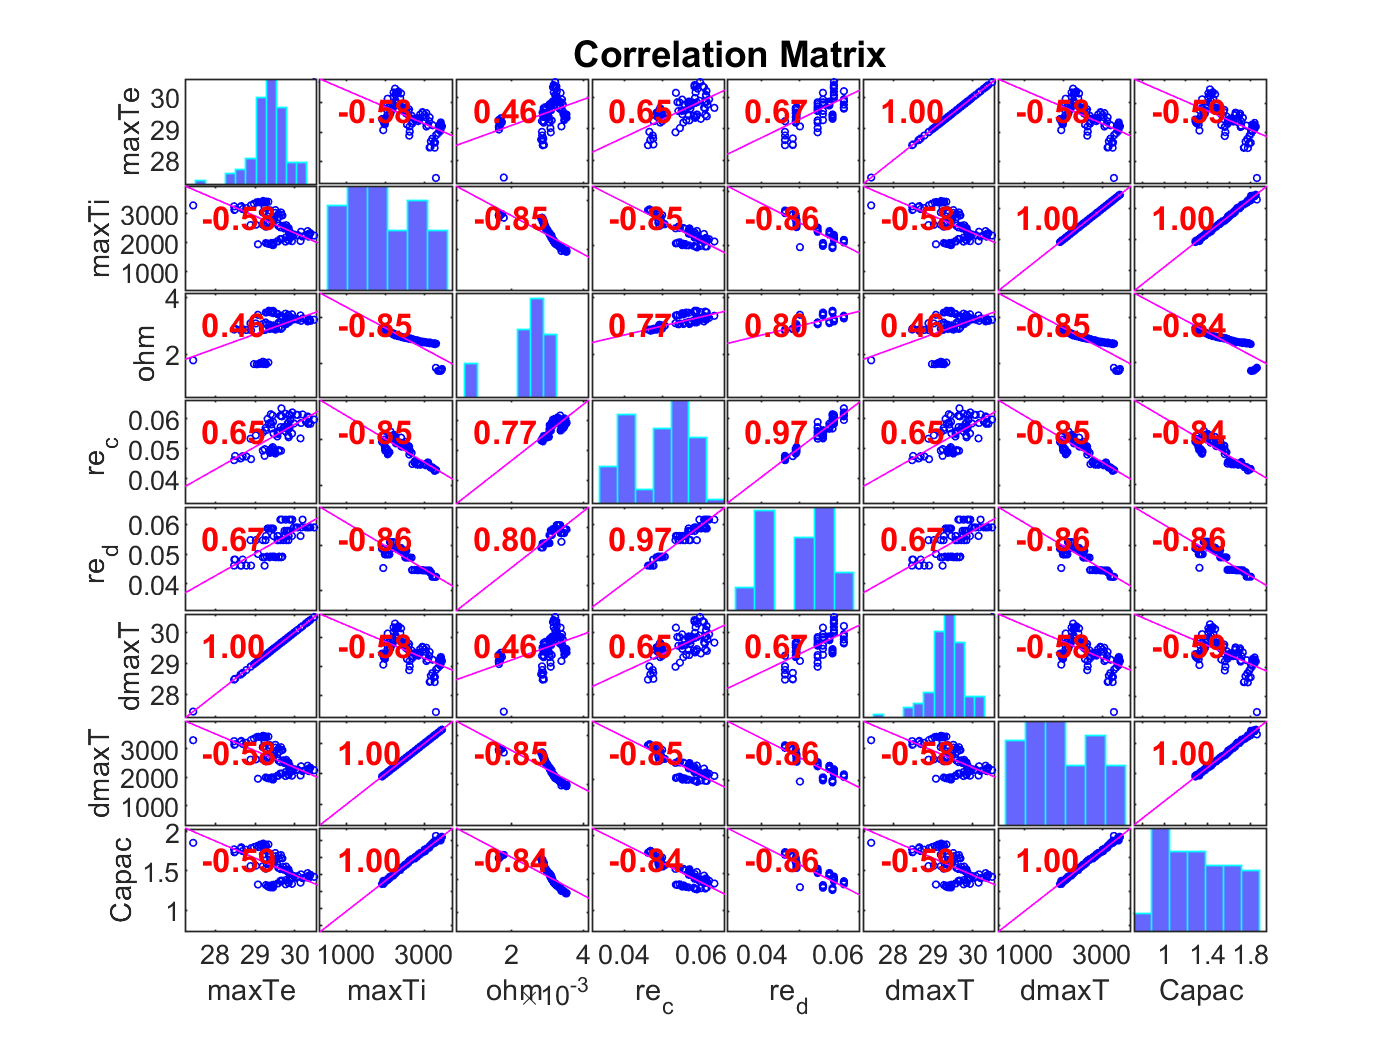

corrplot(dataVectorAll,'type','Pearson','testR','on','varNames',{'maxTemp','maxTimeDelta','ohm','re_c','re_d','dmaxTemp','dmaxTimeDelta','Capacity'})

#### 백터를 테이블로 저장하기

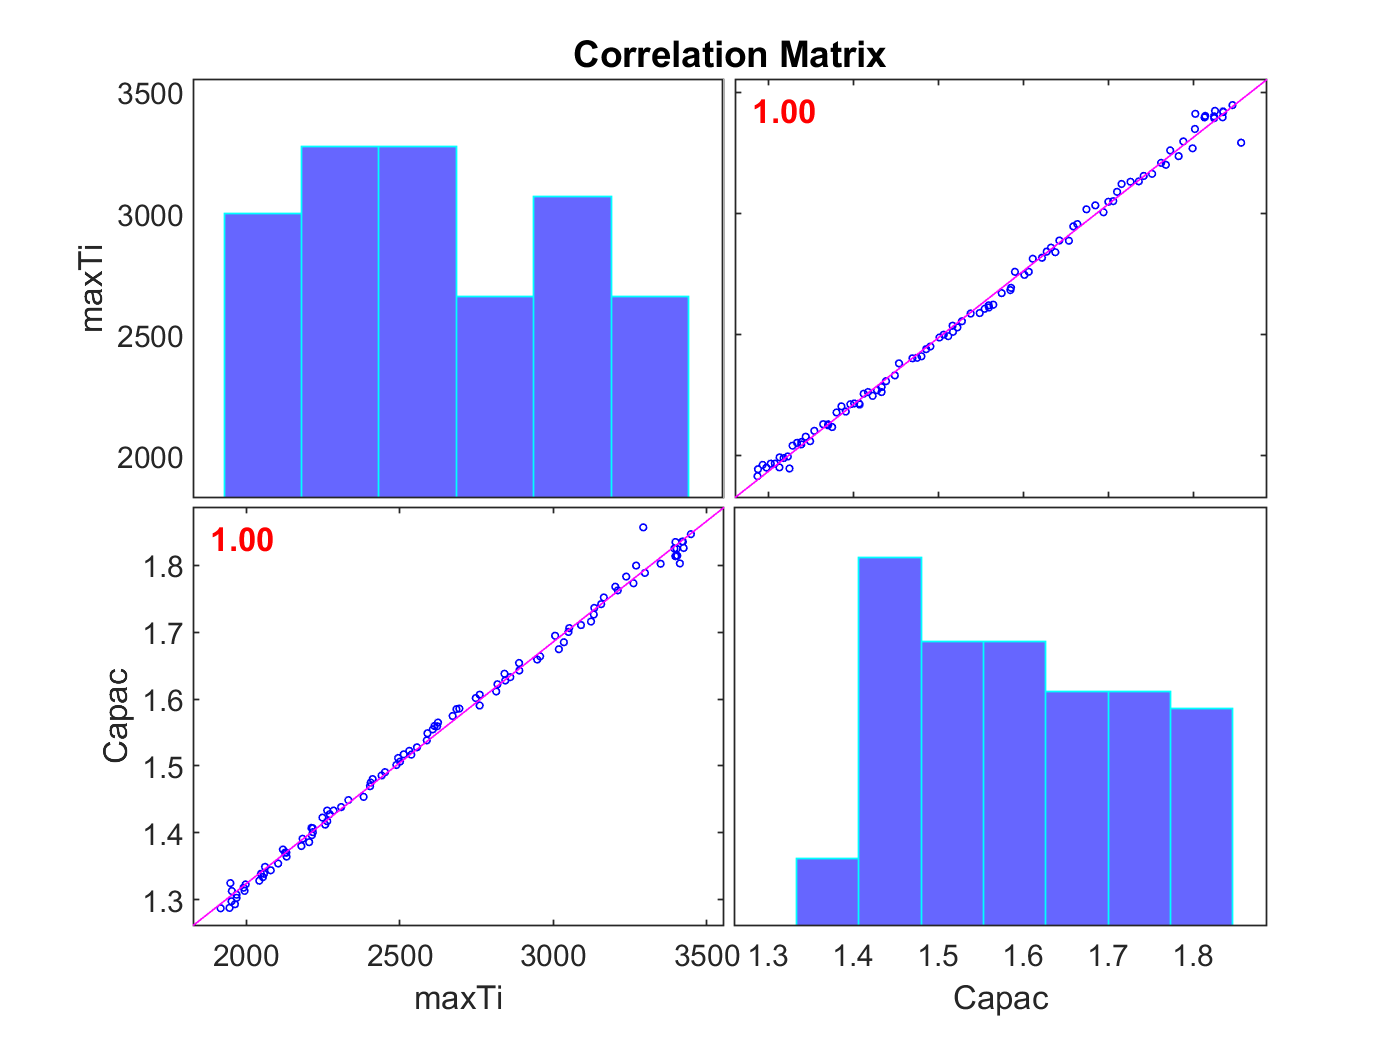

tbl = array2table(dataVector,...
    'VariableNames',{'maxTimeDelta','cap'});
tbl_adj = array2table(dataVector_adj,...
    'VariableNames',{'maxTimeDelta','cap'});
[R,PValue] = corrplot(dataVector,'type','Pearson','testR','on','varNames',{'maxTimeDelta','Capacity'});

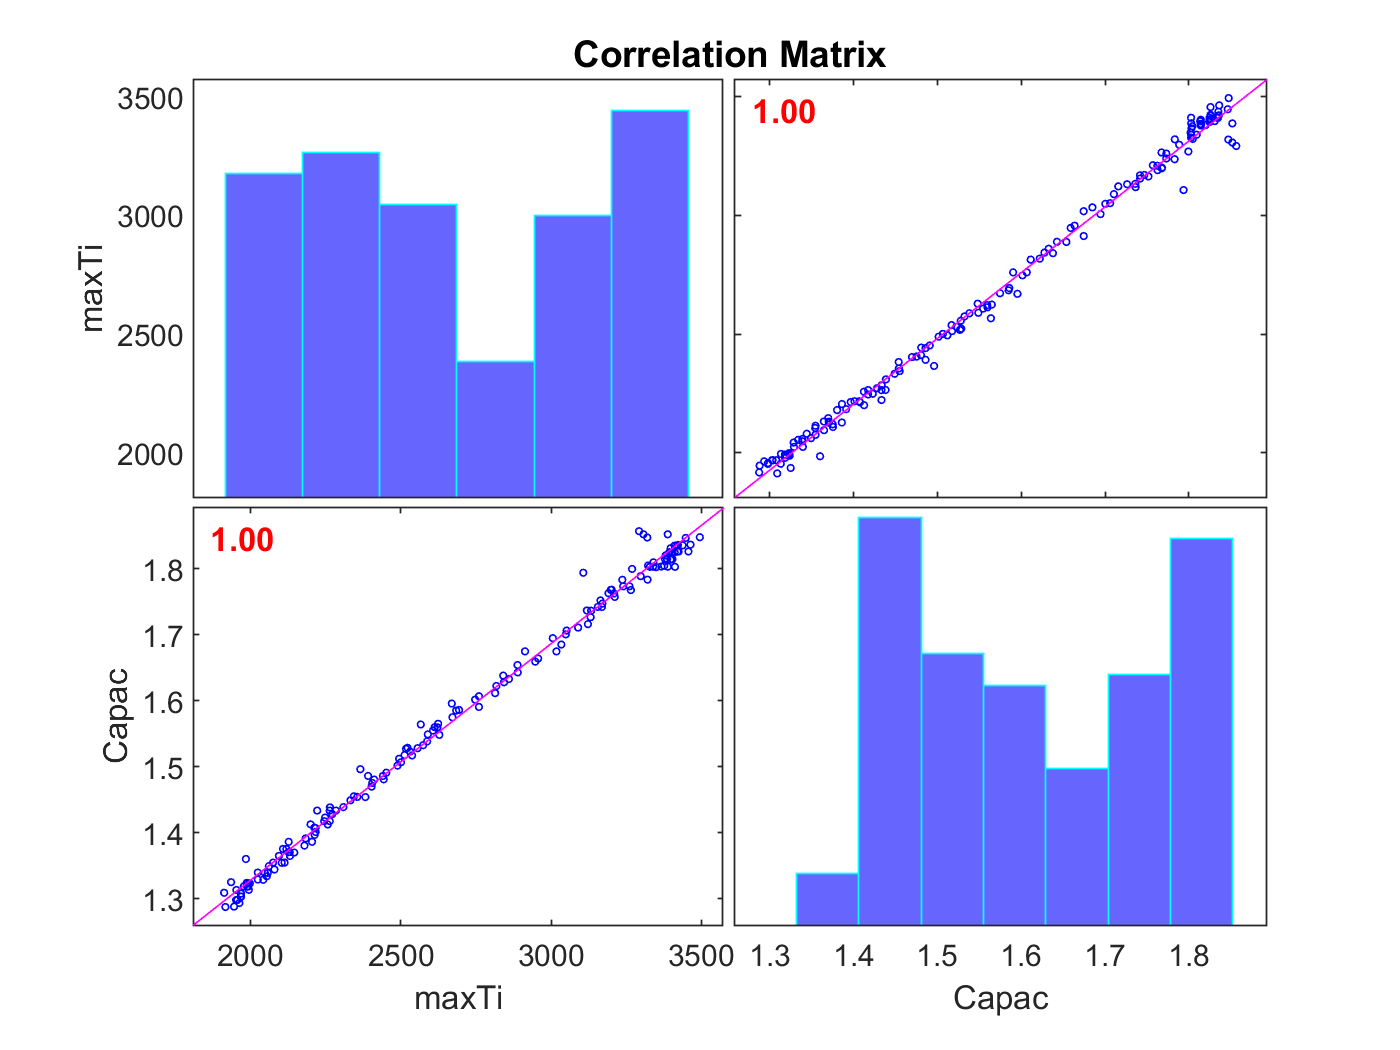

[R,PValue] = corrplot(dataVector_adj,'type','Pearson','testR','on','varNames',{'maxTimeDelta','Capacity'});

#### 참조문서

C:\nobackup\Downloads\Xu_2018_IOP_Conf._Ser.__Mater._Sci._Eng._452_032067.pdf

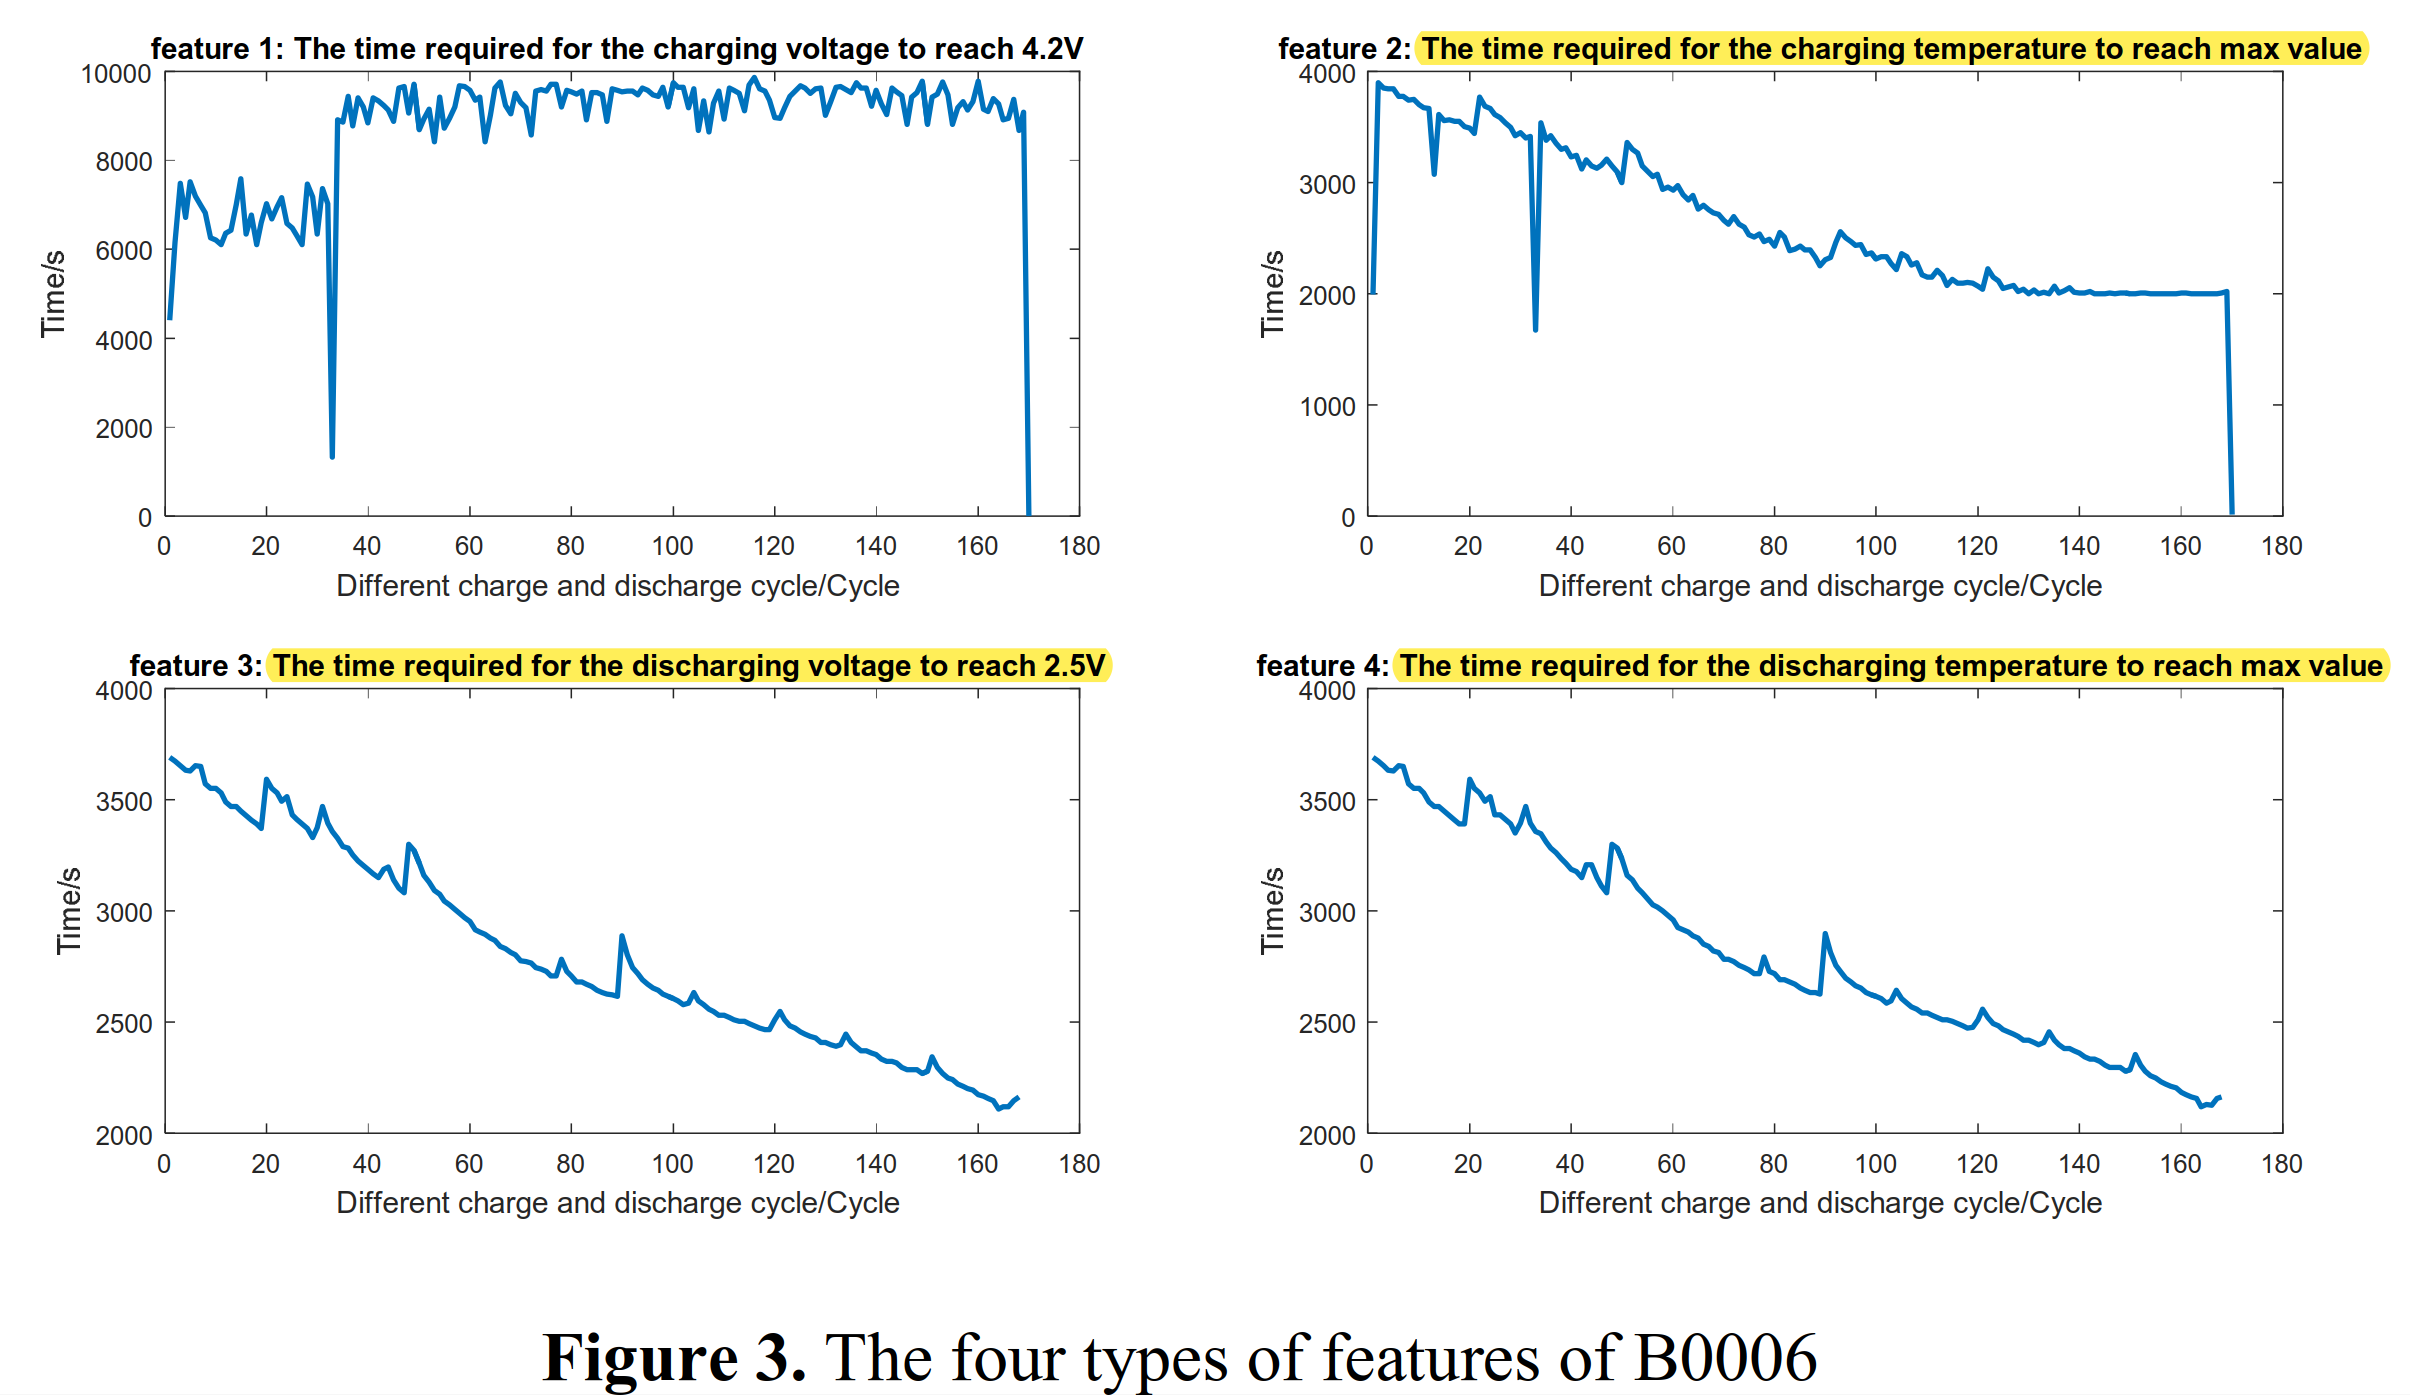

#### 선형회귀에 적용하기


% https://kr.mathworks.com/help/stats/fitlm.html
modelspec = ' cap ~ maxTimeDelta ';
mdl = fitlm(tbl,modelspec )

mdl = Linear regression model:
    cap ~ 1 + maxTimeDelta

Estimated Coefficients:
                     Estimate         SE        tStat       pValue   
                    __________    __________    ______    ___________

    (Intercept)        0.60158     0.0061644    97.589    3.2816e-100
    maxTimeDelta    0.00036132    2.3043e-06     156.8    1.8256e-120


Number of observations: 101, Error degrees of freedom: 99
Root Mean Squared Error: 0.0112
R-squared: 0.996,  Adjusted R-Squared: 0.996
F-statistic vs. constant model: 2.46e+04, p-value = 1.83e-120

mdl_adj = fitlm(tbl_adj,modelspec )

mdl_adj = Linear regression model:
    cap ~ 1 + maxTimeDelta

Estimated Coefficients:
                     Estimate         SE        tStat       pValue   
                    __________    __________    ______    ___________

    (Intercept)        0.61172     0.0057987    105.49    9.3608e-155
    maxTimeDelta    0.00035817    2.1142e-06    169.41    8.7804e-189


Number of observations: 169, Error degrees of freedom: 167
Root Mean Squared Error: 0.0146
R-squared: 0.994,  Adjusted R-Squared: 0.994
F-statistic vs. constant model: 2.87e+04, p-value = 8.78e-189

mdl.Coefficients

ans = 2×4 table
                     Estimate         SE        tStat       pValue   
                    __________    __________    ______    ___________

    (Intercept)        0.60158     0.0061644    97.589    3.2816e-100
    maxTimeDelta    0.00036132    2.3043e-06     156.8    1.8256e-120


mdl_adj.Coefficients

ans = 2×4 table
                     Estimate         SE        tStat       pValue   
                    __________    __________    ______    ___________

    (Intercept)        0.61172     0.0057987    105.49    9.3608e-155
    maxTimeDelta    0.00035817    2.1142e-06    169.41    8.7804e-189


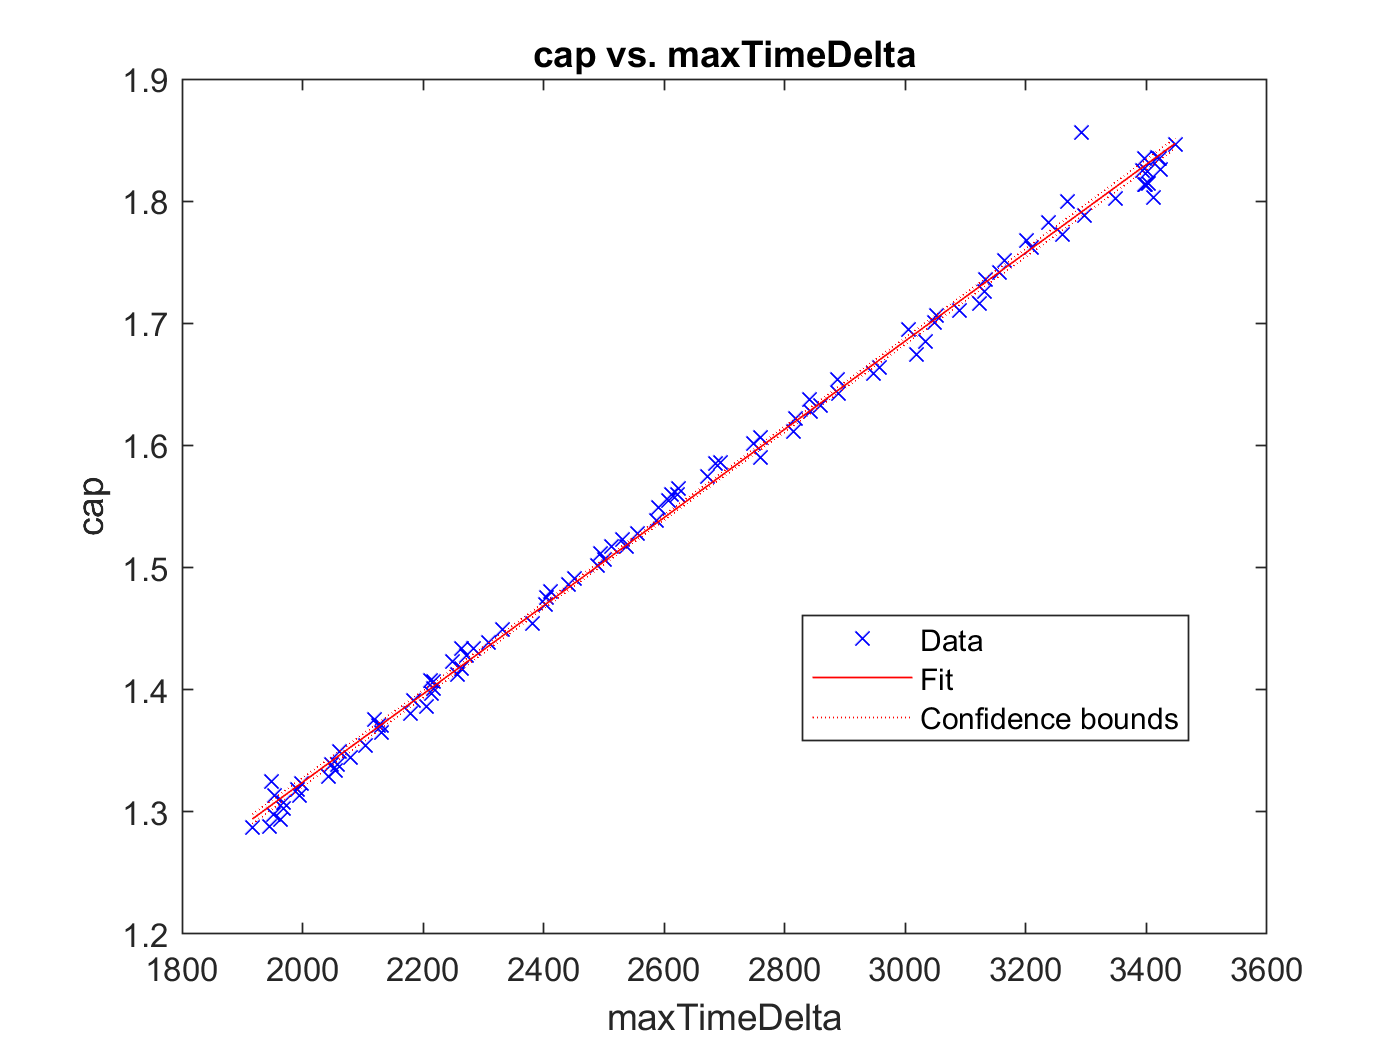

% https://kr.mathworks.com/help/stats/linearmodel.plot.html
plot(mdl)

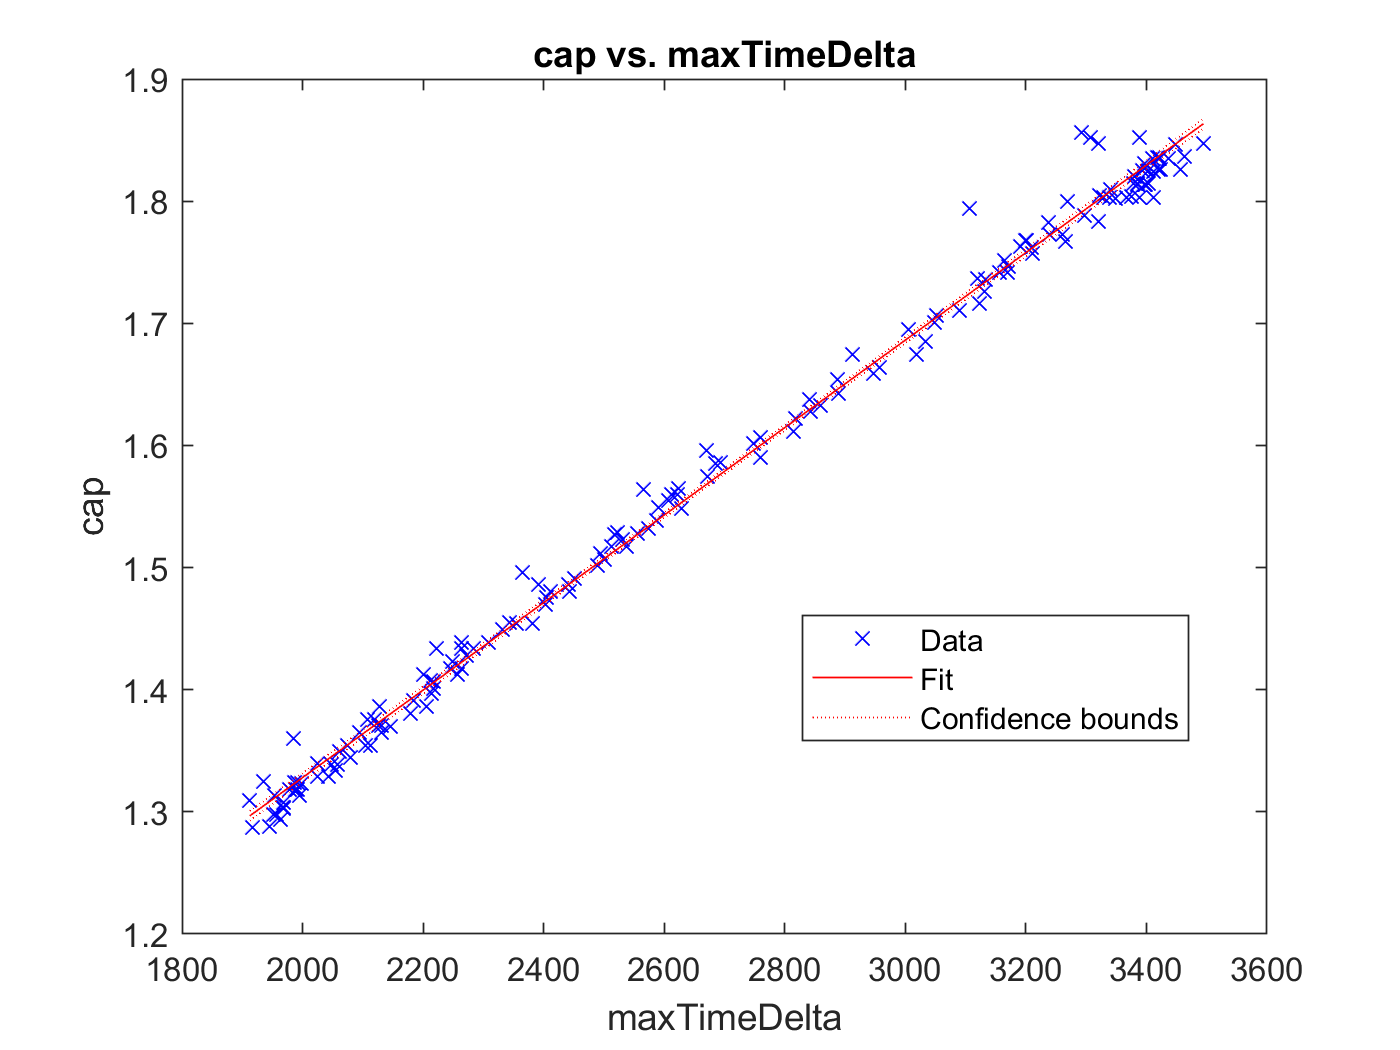

plot(mdl_adj)

모델링된 선형회구식을 가지고 원래 데이타와 예측한 데이타를 비교하자

차이가 많이 난다.

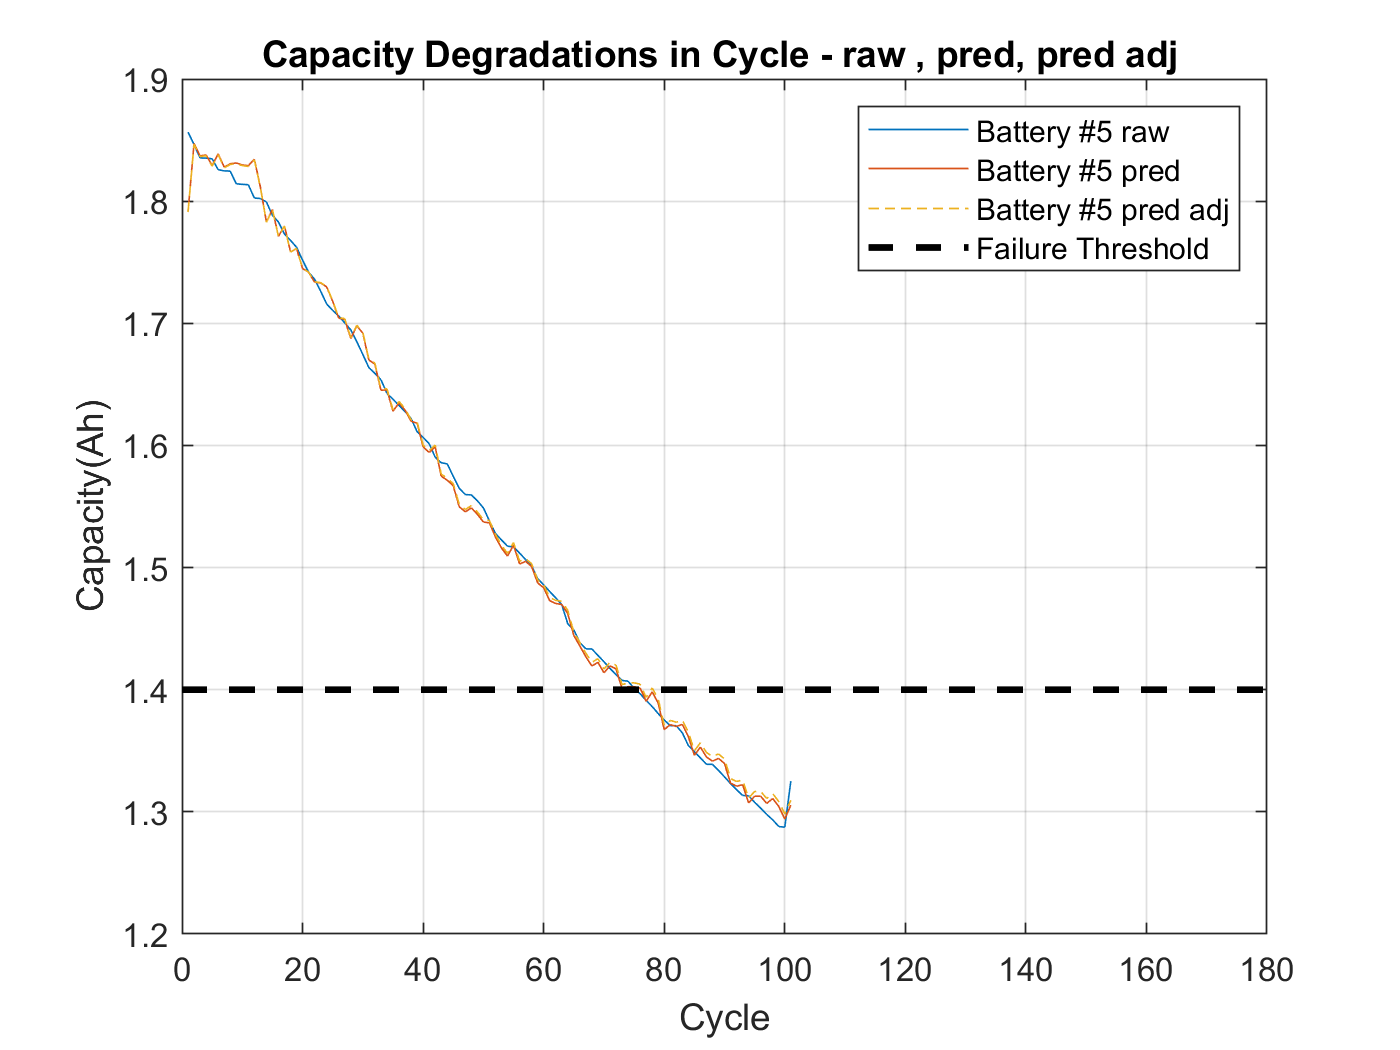

cap5 = cap;
cap5hat = table2array(mdl.Coefficients(1,1)) ...
    + table2array(mdl.Coefficients(2,1))*maxTimeDelta ;
cap5hat_adj = table2array(mdl_adj.Coefficients(1,1)) ...
    + table2array(mdl_adj.Coefficients(2,1))*maxTimeDelta ;

figure
plot(cap5), hold on, plot(cap5hat','-'),plot(cap5hat_adj,'--')
plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5 raw', 'Battery #5 pred', 'Battery #5 pred adj','Failure Threshold')
title('Capacity Degradations in Cycle - raw , pred, pred adj ')

모델설정후 잔차에 대한 히스토그램을 그린다.

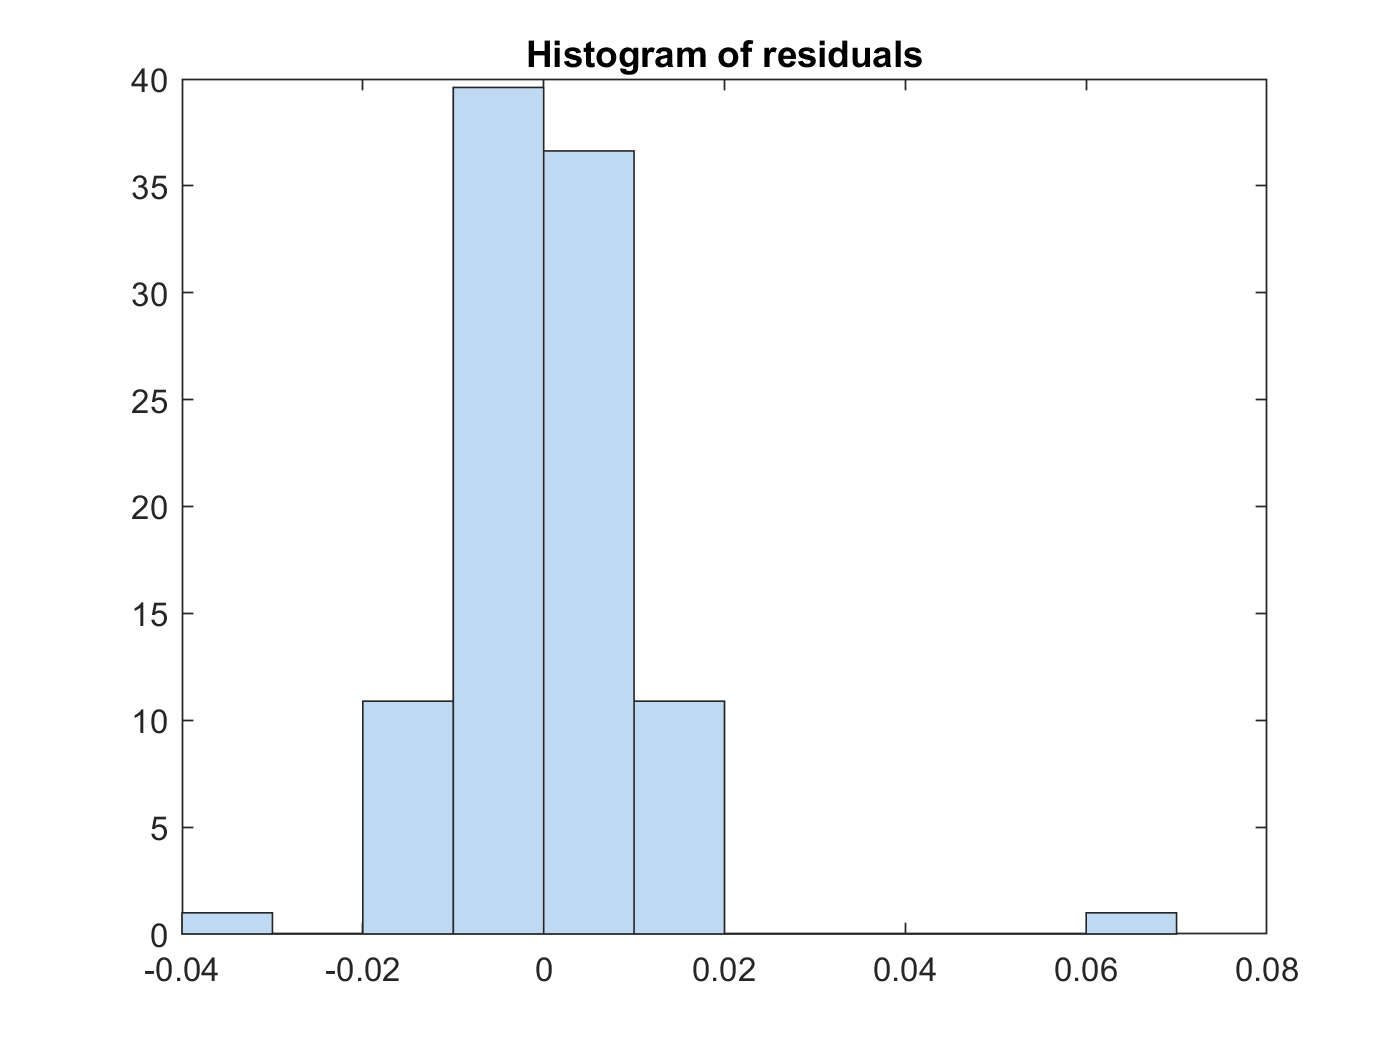

plotResiduals(mdl)

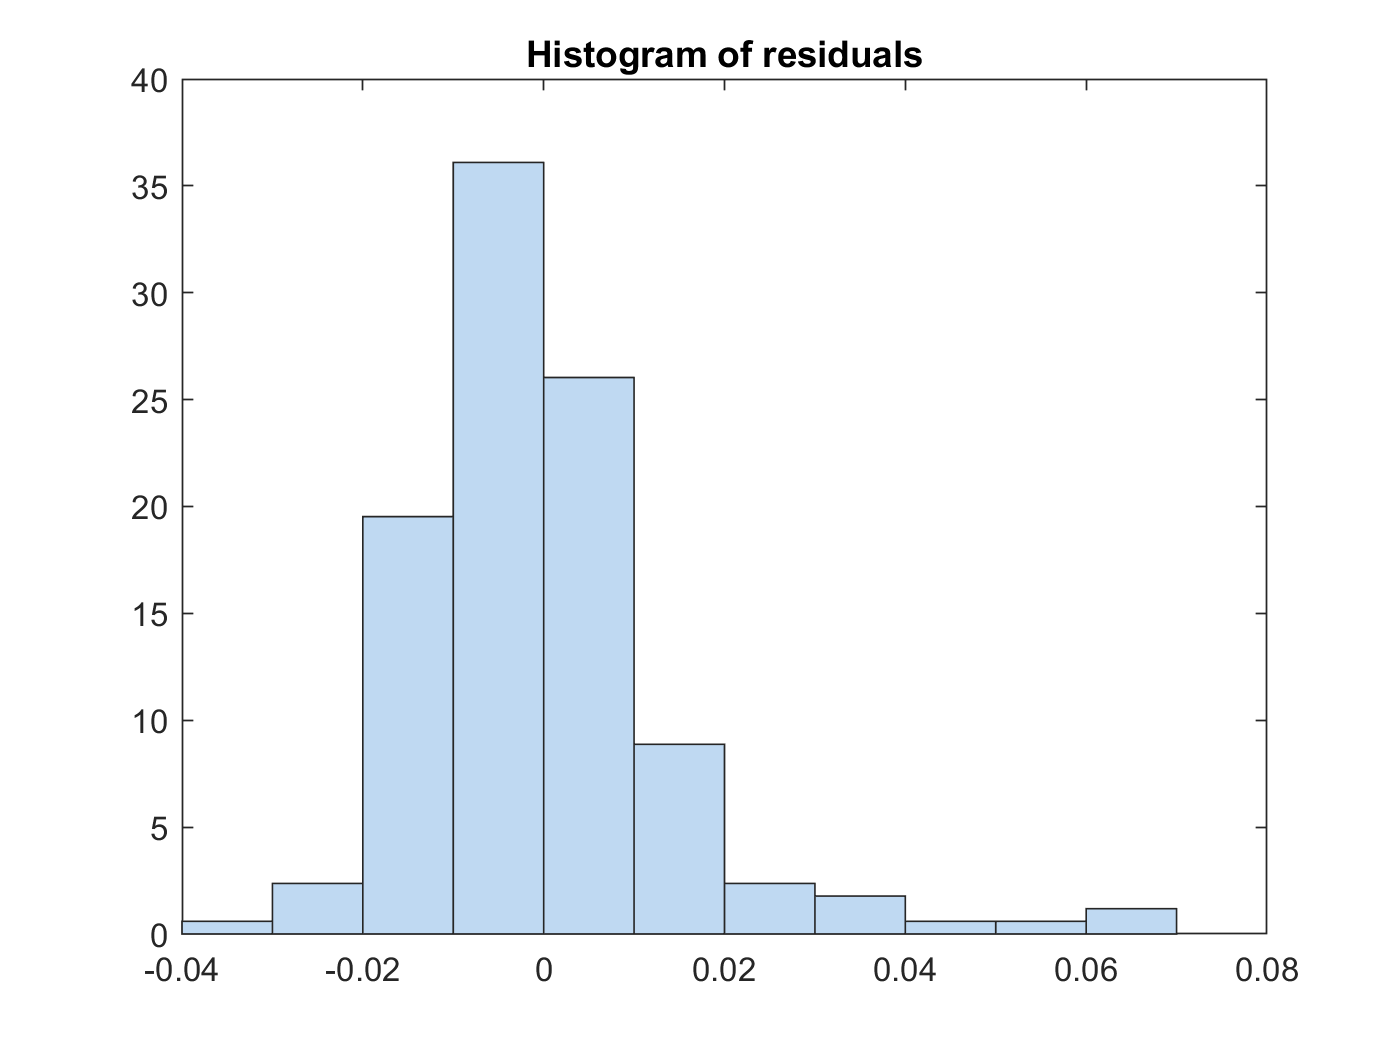

plotResiduals(mdl_adj)

전차가 큰 것이 두개가 보인다. 이를 제거하자

outlier = mdl.Residuals.Raw > 0.2;
find(outlier)


ans =

  0×1 empty double column vector



모델에 사용된 데이타에서 outer 를 제외하고 모델링하라.

mdl1 = fitlm(tbl,modelspec,...
    'Exclude',find(outlier));

outer 정보 출력

mdl1.ObservationInfo(find(outlier),:)


ans =

  0×4 empty table



outer를 제거 후 회귀선이 잘 그려지는지 확인하자.

plot(mdl1)

모델링된 선형회구식을 가지고 원래 데이타와 예측한 데이타를 비교하자

차기가 많이 줄어들었다.

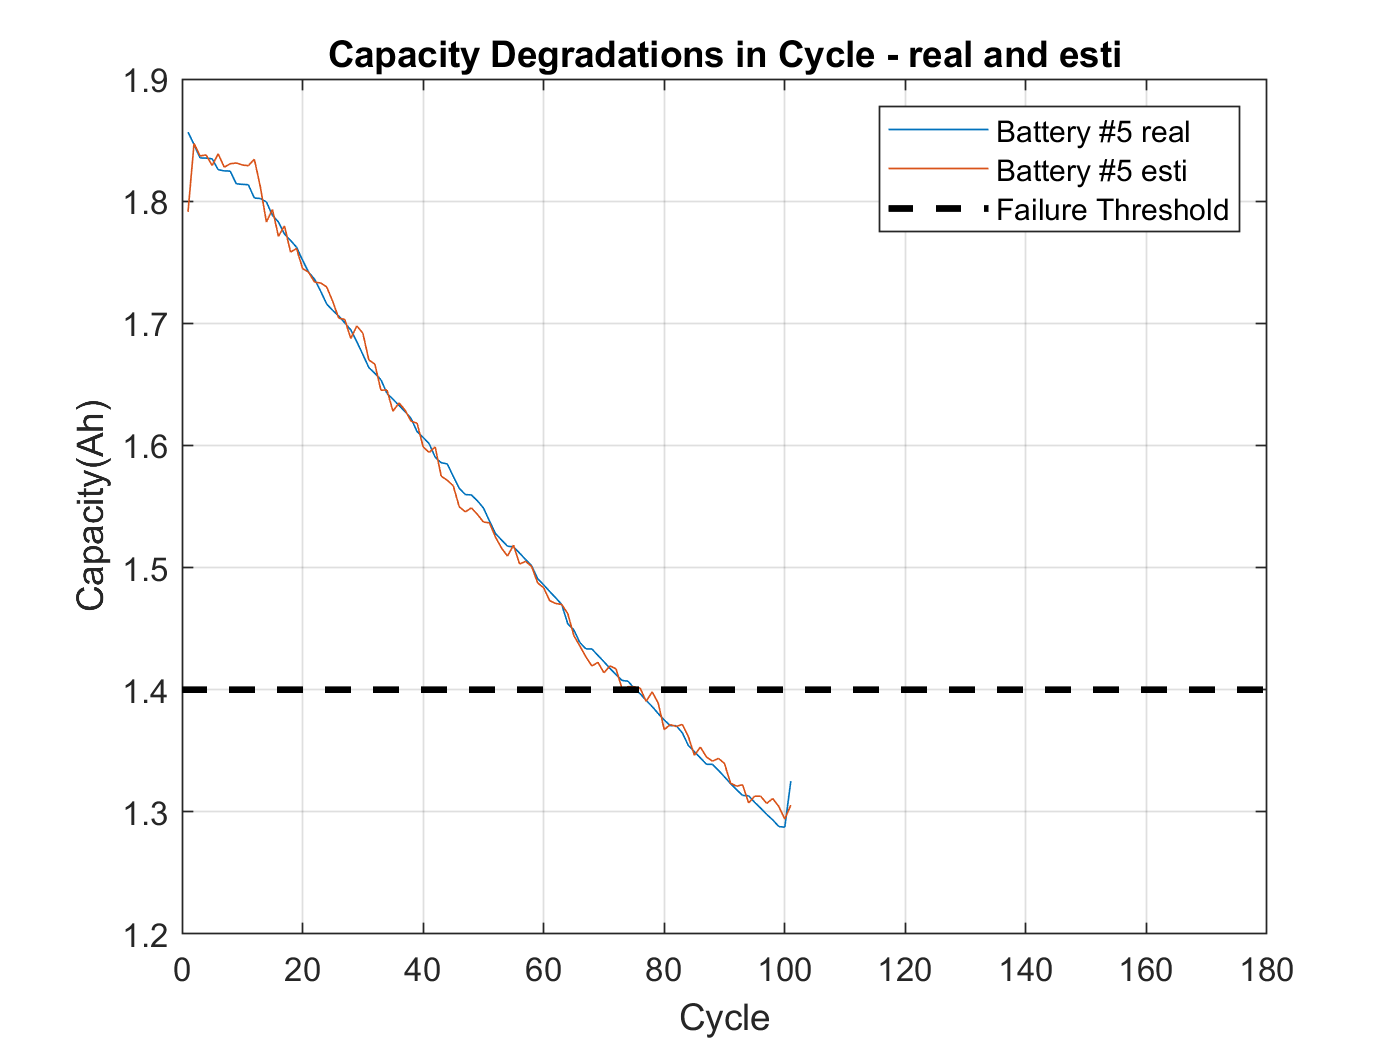


cap5hat = table2array(mdl1.Coefficients(1,1)) ...
    + table2array(mdl1.Coefficients(2,1))*maxTimeDelta ;

figure
plot(cap5), hold on, plot(cap5hat')
plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5 real', 'Battery #5 esti', 'Failure Threshold')
title('Capacity Degradations in Cycle - real and esti')

아래는 다변량 선형회귀에서 변수를 줄이기 위한 것이다.

mdl1 = step(mdl,'NSteps',10)

No terms to add to or remove from initial model.


mdl1 = Linear regression model:
    cap ~ 1 + maxTimeDelta

Estimated Coefficients:
                     Estimate         SE        tStat       pValue   
                    __________    __________    ______    ___________

    (Intercept)        0.60158     0.0061644    97.589    3.2816e-100
    maxTimeDelta    0.00036132    2.3043e-06     156.8    1.8256e-120


Number of observations: 101, Error degrees of freedom: 99
Root Mean Squared Error: 0.0112
R-squared: 0.996,  Adjusted R-Squared: 0.996
F-statistic vs. constant model: 2.46e+04, p-value = 1.83e-120

plot(mdl1)

plotResiduals(mdl1)

모델링된 선형회귀식을 가지고 원래 데이타와 예측한 데이타를 비교하자


cap5hat = table2array(mdl1.Coefficients(1,1)) ...
    + table2array(mdl1.Coefficients(2,1))*maxTimeDelta ;

figure
plot(cap5), hold on, plot(cap5hat')
plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5 real', 'Battery #5 esti', 'Failure Threshold')
title('Capacity Degradations in Cycle - real and esti')

4.09585292607480	0.227155110205607	18.0310842330048	7.46164930980593e-41

-0.0952839654207921	0.00835224901979087	-11.4081806223706	1.35336543592271e-22

0.000196894463615833	1.30246355211347e-05	15.1170804969044	5.83185913112480e-33

-82.6228614134608	13.4185717416945	-6.15735139357142	5.43873148600241e-09




testend =1;